## Identification of differentially expressed proteins

In this section, we will identify DEPs of  Explant patient data, preprocssed by Mimi.

clear
clc
close all

#### 1. data loading

filename='Explant_ResponseGroup_Allprot.xlsx';
% expression data
tbl_exp_dat = readtable(filename,...
    'Range','B1:AP3767',...
    'Sheet','DataMatrix',...
    'ReadVariableNames',true,...
    'ReadRowNames',true);

tbl_exp_dat

tbl_exp_dat = 3766×40 table
                   V_1         V_2         V_3           V_9           V_15          V_19          V_21          V_28          V_31          V_32          V_34        V_36      V_38        V_40          V_41          V_42          V_44          V_6           V_7           V_10        V_12        V_14          V_22        V_24        V_25          V_26        V_27      V_33        V_37        V_43       V_46        V_4       


% response data (labels for ML)
tbl_label_dat = readtable(filename,...
    'Range','C3770:AP3770',...
    'Sheet','DataMatrix',...
    'ReadVariableNames',false);


tbl_label_dat.Properties.VariableNames = tbl_exp_dat.Properties.VariableNames;
tbl_label_dat

tbl_label_dat = 1×40 table
     V_1       V_2       V_3       V_9       V_15      V_19      V_21      V_28      V_31      V_32      V_34      V_36      V_38      V_40      V_41      V_42      V_44      V_6       V_7       V_10      V_12      V_14      V_22      V_24      V_25      V_26      V_27      V_33      V_37      V_43      V_46      V_4       V_5       V_8       V_11      V_13  


% Read Ki67 response data
tbl_Ki67_dat = readtable(filename,...
    'Range','C3768:AP3769',...
    'Sheet','DataMatrix',...
    'ReadVariableNames',false);
tbl_Ki67_dat.Properties.RowNames = {'DMSO','17AAG'}

tbl_Ki67_dat = 2×40 table
              Var1     Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10     Var11     Var12     Var13     Var14     Var15     Var16     Var17     Var18     Var19      Var20     Var21     Var22      Var23     Var24      Var25      Var26     Var27     Var28     Var29     Var30     Var31     Var32     Var33     Var34     Var35     Var36


Ki_ratio = array2table(table2array(tbl_Ki67_dat(2,:))./table2array(tbl_Ki67_dat(1,:)));

tbl_Ki67_ratio_dat = [tbl_Ki67_dat;Ki_ratio];
tbl_Ki67_ratio_dat.Properties.RowNames{3} = 'Ratio';


%[pval(ii,1),tbl,stats] = anova1(table2array(tbl_exp_dat(1,:))',table2array(tbl_label_dat)','off');
 

% % composition of data table
% exp_data = table2array(tbl_exp_dat(:,2:end));
% resp_class = table2array(tbl_label_dat);
% gene_names=tbl_exp_dat.GeneName; 


## IMPUTATION OF MSSING VALUE

Note: the missing values are idnciated by a number less than 1.

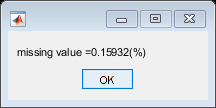

tmp_exp = table2array(tbl_exp_dat);

[rr,cc]=size(tmp_exp);

msg = strcat( 'missing value = ',num2str(length(tmp_exp(tmp_exp<1))/(rr*cc) * 100),'(%)');
f = msgbox(msg);


% imputation
loc_undect = (or(tmp_exp==1,tmp_exp==0));
sz_undect = sum(loc_undect(:));
% numcl2(loc_undect)

% uniform dist from 0 to 1
ub = 1; lb = 0;
% for conrol random number generator
rng(1) 
rand_num= ub - (ub - lb)*rand(sz_undect,1);

% imputate the rowdata
tmp_exp = tmp_exp;
tmp_exp(loc_undect)=rand_num;

tbl_exp_dat_imp=array2table(tmp_exp);
tbl_exp_dat_imp.Properties.VariableNames = tbl_label_dat.Properties.VariableNames;
tbl_exp_dat_imp.Properties.RowNames = tbl_exp_dat.Properties.RowNames;

tmp_exp = [];

## ANOVA analysis

parfor ii = 1:size(tbl_exp_dat_imp,1)
    % disp(ii)
    [pval(ii,1),~,~] = anova1(table2array(tbl_exp_dat_imp(ii,:))',table2array(tbl_label_dat)','off');
end

## Regression analysis

parfor ii = 1:size(tbl_exp_dat_imp,1)
    % disp(ii)
    [rho(ii,1),pval2(ii,1)] = corr(table2array(tbl_exp_dat_imp(ii,:))',table2array(tbl_Ki67_ratio_dat(3,:))');
end

%tbl_exp_dat_short = tbl_exp_dat_imp;
%tbl_exp_dat_short(~and(abs(rho)>0.3, pval <0.05),:)=[];

## DEGs

cut_off = 0.05;
tbl_exp_deg = tbl_exp_dat_imp;
tbl_exp_deg(pval>cut_off,:) = []

tbl_exp_deg = 157×40 table
                  V_1           V_2           V_3           V_9           V_15         V_19        V_21        V_28        V_31      V_32      V_34      V_36      V_38      V_40      V_41      V_42      V_44        V_6           V_7           V_10          V_12          V_14        V_22      V_24      V_25      V_26        V_27        V_33        V_37        V_43        V_46          V_4           V_5        


tmp_pval = pval;
tmp_pval(tmp_pval>cut_off,:) = [];
DEG_pval = array2table(tmp_pval,'RowNames',tbl_exp_deg.Properties.RowNames);


## heatmap(1) for DEG

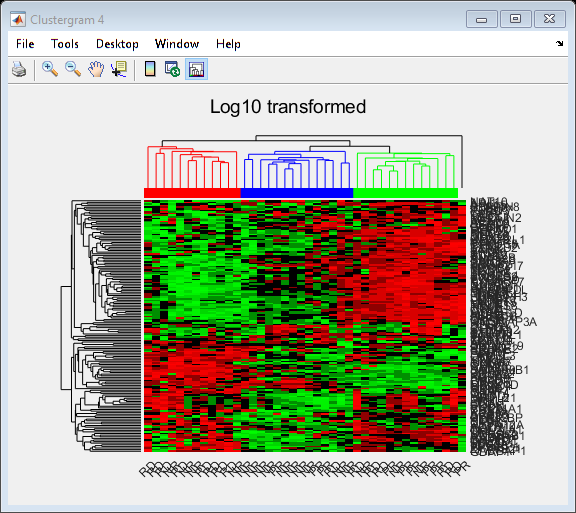

Column_Labels = table2array(tbl_label_dat);
Row_Labels = tbl_exp_deg.Properties.RowNames;
exp_dat = log10(table2array(tbl_exp_deg));
hmo = clustergram(exp_dat,...
    'Cluster','all',...
    'Standardize',2,...
    'RowLabels',Row_Labels,...
    'ColumnLabels',Column_Labels,...
    'ColumnLabelsRotate',45);

cm = struct('GroupNumber',{36,33,31},...
    'Annotation',{'Group1','Group2','Group3'},...
    'Color',{'Red','Blue','Green'});
set(hmo,'ColumnGroupMarker',cm)
% hmo.RowLabels = {};
hmo.addTitle('Log10 transformed')

Group1 = clusterGroup(hmo,36,'column','Color','Red');
Group2 = clusterGroup(hmo,33,'column','Color','Blue');
Group3 = clusterGroup(hmo,31,'column','Color','Green');

## heatmap(2) for all gene sets

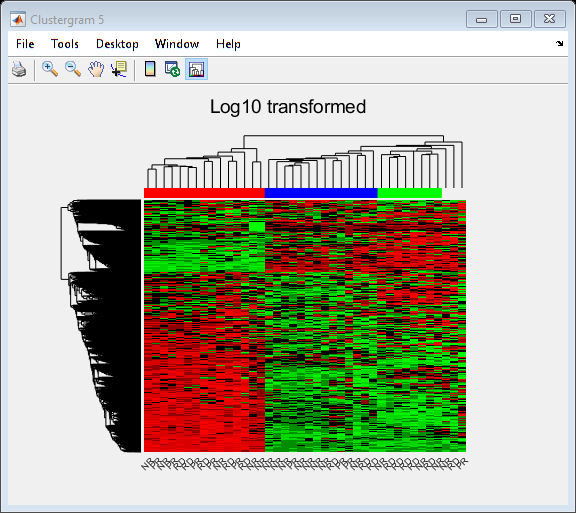

Column_Labels = table2array(tbl_label_dat);
Row_Labels = tbl_exp_dat_imp.Properties.RowNames;
exp_dat = log10(table2array(tbl_exp_dat_imp));

hmo = clustergram(exp_dat,...
    'Cluster','all',...
    'Standardize',2,...
    'RowLabels',Row_Labels,...
    'ColumnLabels',Column_Labels,...
    'ColumnLabelsRotate',45);

cm = struct('GroupNumber',{35,33,32},...
    'Annotation',{'Group1','Group2','Group3'},...
    'Color',{'Red','Blue','Green'});
set(hmo,'ColumnGroupMarker',cm)
% hmo.RowLabels = {};
hmo.addTitle('Log10 transformed')


%% code for future
% % import bioma.data.*
% % DMobj = DataMatrix(table2array(tbl_exp_deg), tbl_exp_deg.Properties.RowNames, tbl_exp_deg.Properties.VariableNames);
% % 
% % clustergram(DMobj,...
% %     'Cluster','all',...
% %     'Standardize',2,...
% %     'ColumnLabelsRotate',45)

## Making a color bar for classes

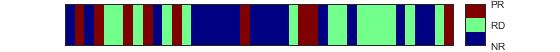

figure('Position',[681   927   560    52]);
colormap([0 0 0.515625;0.453125 1 0.546875;0.5 0 0])

ColumnLabels = hmo.ColumnLabels;

A_bar = zeros(size(ColumnLabels));
A_bar(ismember(ColumnLabels,{'NR'}))=1;
A_bar(ismember(ColumnLabels,{'RD'}))=2;
A_bar(ismember(ColumnLabels,{'PR'}))=3;

% plot with standard settings

im = imagesc(A_bar);
caxis([1 3]);
xticklabels({})
xticks({})
yticklabels({})
yticks({})

mycb = colorbar();
set(mycb, 'YTick', [1 2 3], 'YTickLabel', {'NR', 'RD', 'PR'});

## Pie chart

Group1 = clusterGroup(hmo,35,'column','Color','Red');
Group2 = clusterGroup(hmo,33,'column','Color','Blue');
Group3 = clusterGroup(hmo,32,'column','Color','Green');

figure('Position',[681   498   231   481]),
X1 = categorical(Group1.ColumnLabels);
subplot(1,3,1),pie(X1)
pbaspect([4 3 1])
title('Group 1','Color','red')

X2 = categorical(Group2.ColumnLabels);
subplot(1,3,2),pie(X2)
pbaspect([4 3 1])
th1 = title('Group 2','Color','blue');
get(th1,'Position')

ans =     0.0000    1.3078         0


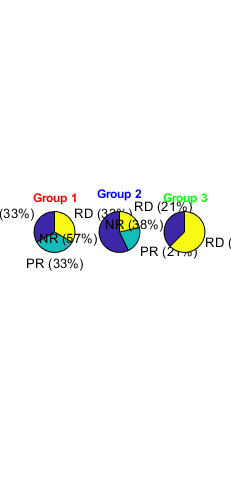

set(th1,'Position',[0.0000 1.5 0]);

X3 = categorical(Group3.ColumnLabels);
subplot(1,3,3),pie(X3)
pbaspect([4 3 1])
title('Group 3','Color','green')

## Save the DEG data

fpath = 'outcomes\Explant_ResponseGroup_Allprot_DEGs.xlsx';

writetable(tbl_exp_deg,fpath,...
    'Sheet','DEG expression',...
    'WriteVariableNames',true,...
    'WriteRowNames',true)

Unable to save the workbook to file 'C:\Users\sshin\OneDrive - Monash University\RESEARCH\___BioMarker_17AAG\Code_master\Matlab\Revision_Jun_2021\outcomes\Explant_ResponseGroup_Allprot_DEGs.xlsx'. Check that write permissions are available, there is sufficient disk space, and the file can be written to or created.


writetable(DEG_pval,fpath,...
    'Sheet','DEG pvals',...
    'WriteVariableNames',true,...
    'WriteRowNames',true)

writetable(tbl_label_dat,fpath,...
    'Sheet','Target labels',...
    'WriteVariableNames',true,...
    'WriteRowNames',true)